clc, clearvars, close all
% Synthesis of H infty regulator for island mode, requiers TDS toolbox:
% https://gitlab.kuleuven.be/u0011378/tds-control

s = tf('s');

% Parameters
p = params();
cellfun(@(f) assignin('caller',f,p.(f)), fieldnames(p));


omega_p = omega_nom;

% Operating point
fun = @(x) steady_equations(x, p, omega_p, 0);
x0 = [1; 0.2];

sol = fsolve(fun, x0);


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>




V_p = sol(1);
u_p = sol(2);

Q_p = A * V_p;
hf_p = f*L/(2*D*g)*V_p^2;
Hb_p = HL - hf_p;

fprintf('Working point:\n');

Working point:


fprintf('V_p = %.3f m/s\n', V_p);

V_p = 0.189 m/s


fprintf('u_p = %.3f\n', u_p);

u_p = 0.065


fprintf('Q_p = %.3f m3/s\n', Q_p);

Q_p = 3.009 m3/s


fprintf('Hb_p = %.3f m\n', Hb_p);

Hb_p = 169.999 m



% Lineariztion

B  = (g*A)/a;
Kh = (k*u_p)/(2*sqrt(Hb_p-Ht));
Ku = k*sqrt(Hb_p-Ht);
CQ = (rho*g*eta_t)*(Hb_p-Ht)/omega_p;
CH = (rho*g*eta_t)*Q_p/omega_p;
Cw = (rho*g*eta_t)*Q_p*(Hb_p-Ht)/omega_p^2;
Dw = b+c*omega_p; % linearization of losses 
T  = I/(Cw+Dw);
tau = (Nx-1)*dt;

delay = exp(-2*tau*s);

num_h = (B*CQ - CH) + (B*CQ + CH)*delay;
den_h = (Kh + B) + (B - Kh)*delay;

G_h = Ku * num_h / den_h;
G_f    = 1 / (Tw*s + 1);


G_mech = 1 / ((Cw+Dw)*(T*s + 1));
G = G_h * G_mech*G_f;


%%% State space - island mode
a0 = Kh+B;
a1 = B-Kh;
b0 = Ku*(B*CQ-CH);
b1 = Ku*(B*CQ+CH);
delta = 2*tau;

% State space matrices
A1p = [0 1; -1/(T*Tw) -(T+Tw)/(T*Tw)];
A2p = [0 0; -a1/(a0*T*Tw) -(a1*(T+Tw))/(a0*T*Tw)];
H1p = [0 0; 0 a1/a0];
B11p = [0; b0/(a0*T*Tw*(Cw+Dw))];
B12p = [0; b1/(a0*T*Tw*(Cw+Dw))];
Cp = [1 0];

sys = tds_create_neutral({H1p},delta,{A1p,A2p},[0 delta],{B11p, B12p},[0 delta],{Cp},0);

disp('Poles of the neutral system: ')

Poles of the neutral system: 


roots = tds_roots(sys,[-80 0 -200 200])

Degree of the spectral discretisation is 33.


roots = 1.0e+02 *

  -0.0074 + 1.7868i
  -0.0074 - 1.7868i
  -0.0074 + 1.5119i
  -0.0074 - 1.5119i
  -0.0074 + 1.2370i
  -0.0074 - 1.2370i
  -0.0074 + 0.9621i
  -0.0074 - 0.9621i
  -0.0074 + 0.6872i
  -0.0074 - 0.6872i


disp('Zeros of the neutral system: ')

Zeros of the neutral system: 


nul = tds_tzeros(sys,[0 3 -200 200])

Degree of the spectral discretisation is 27.


nul = 1.0e+02 *

   0.0149 + 1.7868i
   0.0149 - 1.7868i
   0.0149 + 1.5119i
   0.0149 - 1.5119i
   0.0149 + 1.2370i
   0.0149 - 1.2370i
   0.0149 + 0.9621i
   0.0149 - 0.9621i
   0.0149 + 0.6872i
   0.0149 - 0.6872i



tol = 1e-12;

% poles division according to Re(lambda)
rr = roots(real(roots) > tol);
rg = roots(real(roots) < -tol);
rb = roots(abs(real(roots)) <= tol);

% zeros dvision according to Re(lambda)
lr = nul(real(nul) > tol);
lg = nul(real(nul) < -tol);
lb = nul(abs(real(nul)) <= tol);


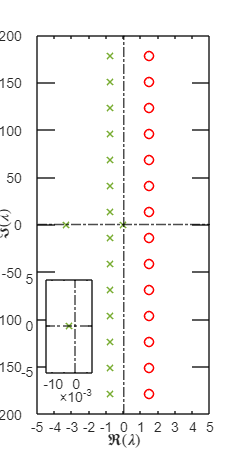

% PZ Map - modified function based on tds_eigenplot
figure; hold on; box on;

% poles
if ~isempty(rr)
    plot(real(rr), imag(rr), 'rx', 'MarkerSize',6, 'LineWidth',1);
end

if ~isempty(rg)
    plot(real(rg), imag(rg), 'x', ...
        'Color',[0.4660 0.6740 0.1880], ...
        'MarkerSize',6, 'LineWidth',1);
end

if ~isempty(rb)
    plot(real(rb), imag(rb), 'bx', ...
        'MarkerSize',6, 'LineWidth',1);
end

% zeros
if ~isempty(lr)
    plot(real(lr), imag(lr), 'ro', 'MarkerSize',6, 'LineWidth',1);
end

if ~isempty(lg)
    plot(real(lg), imag(lg), 'o', ...
        'Color',[0.4660 0.6740 0.1880], ...
        'MarkerSize',6, 'LineWidth',1);
end

if ~isempty(lb)
    plot(real(lb), imag(lb), 'bo', ...
        'MarkerSize',6, 'LineWidth',1);
end

xlim([-5 5]);
ylim([-200 200]);
xticks(-5:1:5)

xline(0,'k-.','LineWidth',1)
yline(0,'k-.','LineWidth',1)

xlabel('$$\Re(\lambda)$$','Interpreter','latex')
ylabel('$$\Im(\lambda)$$','Interpreter','latex')


% ZOOM on pole zlose to 0
ax_zoom = axes('Position',[0.2 0.2 0.2 0.2]);
hold(ax_zoom,'on'); box(ax_zoom,'on');

plot(ax_zoom, real(rr), imag(rr), 'rx', 'MarkerSize',6, 'LineWidth',1);
plot(ax_zoom, real(rg), imag(rg), 'x', ...
    'Color',[0.4660 0.6740 0.1880], ...
    'MarkerSize',6, 'LineWidth',1);
plot(ax_zoom, real(rb), imag(rb), 'bx', ...
    'MarkerSize',6, 'LineWidth',1);

% zoom centre
xc = -0.0027;

% zoom range
xlim(ax_zoom, [xc-0.01 xc+0.01]);
ylim(ax_zoom, [-5 5]);

% axes
xline(ax_zoom,0,'k-.')
yline(ax_zoom,0,'k-.')

set(ax_zoom,'FontSize',7)

grid off
set(gca,'FontSize',9,'GridAlpha',0.2)

set(gcf,'Units','centimeters');
set(gcf,'Position',[0 0 12 24]);


%exportgraphics(gcf,'poles_zeros.pdf','ContentType','vector','Resolution',300);

% Bode plot

Ex = eye(2)+H1p;
Ax = (A1p + A2p);
Bx = (B11p + B12p);

sys0 = ss(Ax,Bx,Cp,0,'E',Ex);
disp(['DC gain of the neutral system: ',num2str(freqresp(sys0,0),3)])

DC gain of the neutral system: 300


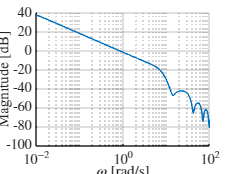


sys = tds_create_neutral({H1p}, delta, {A1p, A2p}, [0 delta], ...
    'B2', {B11p, B12p}, [0 delta], ...
    'C2', {Cp});

% Frequency range
W = logspace(-2, 2, 500);   % rad/s

% Singular values (SISO system)
SV = tds_sigma(sys, W);

% dB
SV_dB = 20*log10(SV);

figure;

semilogx(W, SV_dB, 'LineWidth',1);
grid on
box off

xlabel('$\omega$ [rad/s]', 'Interpreter', 'latex')
ylabel('Magnitude [dB]', 'Interpreter', 'latex')

set(gca,'TickLabelInterpreter','latex')

set(gca, 'XScale', 'log');
xlim([1e-2 1e2]);

set(gca,'FontSize',9,'GridAlpha',0.2)

set(gcf, 'Units', 'centimeters');
set(gcf, 'Position', [0 0 8 6]);


% export
%exportgraphics(gcf, 'bode_ampl_isl.pdf','ContentType','vector','Resolution',300);


%%% Augumented plant

% Disturbance
Gd = ss(1/((s+1)*(T*s+1)*(Cw+Dw)));

Ad = Gd.A;
Bd = Gd.B;
Cd = Gd.C;
Dd = Gd.D;

% Weights 

% State space W1
W1 = ss(100*(1/((s+0.001)*(0.5*T*s+1))));


Aw1 = W1.A;
Bw1 = W1.B;
Cw1 = W1.C;
Dw1 = W1.D;

% State space W3

W3 = ss(0.23*tf(conv(1,conv([0.3 1],[600 1])),conv([0.15 1],[250 1])));

Aw3 = W3.A;
Bw3 = W3.B;
Cw3 = W3.C;
Dw3 = W3.D;


% Second order W3 and Gd present
nu_p = size(A1p,1);
nu_d = size(Ad,1);
nu_w1 = size(Aw1,1);
nu_w3 = size(Aw3,1);


% A_1e
A1e = [
    A1p zeros(nu_p , nu_d + nu_w1 + nu_w3);
    zeros(nu_d,nu_p) Ad zeros(nu_d,nu_w1 + nu_w3);
    -Bw1*Cp Bw1*Cd Aw1 zeros(nu_w1, nu_w3);
    Bw3*Cp zeros(nu_w3, nu_d + nu_w1) Aw3
        ];
% A_2e
A2e = [A2p zeros(nu_p , nu_d + nu_w1 + nu_w3); 
            zeros(nu_d + nu_w1 + nu_w3, nu_p + nu_d + nu_w1 + nu_w3)];
B11e = [B11p; zeros(nu_d + nu_w1 + nu_w3,1)];
B12e = [B12p; zeros(nu_d + nu_w1 + nu_w3,1)];
B2e = [zeros(nu_p,2); Bd zeros(nu_d, 1); zeros(nu_w1, 1) Bw1; zeros(nu_w3,2)];
H1e = [H1p zeros(nu_p,nu_d + nu_w1 + nu_w3); 
            zeros(nu_d + nu_w1 + nu_w3,nu_p + nu_d + nu_w1 + nu_w3)];
% C_1,1e
C1e = [-Cp Cd zeros(1,nu_w1+nu_w3)];
% C_2,1e
C2e = [
    -Dw1*Cp Dw1*Cd Cw1 zeros(1,nu_w3);
    Dw3*Cp zeros(1,nu_d + nu_w1) Cw3
    ] % -Dw3*Cd can be zero, depends if W3 weighs disturbance

C2e =          0         0         0         0         0   17.4305         0         0
    1.1040         0         0         0         0         0   -1.8413   -0.0932


% D_22,1e
D22 = [0 Dw1; 0 0];
% D_11,1e
D11 = 0;
% D_12,1e
D12 = [0 1];
% D_21,1e
D21 = [0;0];

sys = tds_create_neutral({H1e},delta,{A1e,A2e},[0 delta],{B11e, B12e},[0 delta],{C1e},0,...
'D12',{D12},'B2',{B2e},'C2',{C2e},'D22',{D22})

sys = LTI Neutral Time-Delay State-Space System with properties:

       H: {[8×8 double]}
      hH: 0.2286
      mH: 1
       A: {[8×8 double]  [8×8 double]}
      hA: [0 0.2286]
      mA: 2
      B1: {[8×1 double]  [8×1 double]}
     hB1: [0 0.2286]
     mB1: 2
      C1: {[-1 0 0 0.0020 0 0 0 0]}
     hC1: 0
     mC1: 1
      B2: {[8×2 double]}
     hB2: 0
     mB2: 1
      C2: {[2×8 double]}
     hC2: 0
     mC2: 1
     D12: {[0 1]}
    hD12: 0
    mD12: 1
     D22: {[2×2 double]}
    hD22: 0
    mD22: 1
       n: 8
      p1: 1
      q1: 1
      p2: 2
      q2: 2


ny = 1; nu = 1; nc = 2;
% optimize everything via mask
mask  = ss(zeros(nc,nc), zeros(nc,nu), ones(nu,nc), 1);
s = tf('s');

C = pid(5.5,1.8519,0.3403,0.04);
C_ss = ss(C,'minimal');
basisA = C_ss.A;
basisB = C_ss.B;
basis = ss(basisA, basisB, zeros(nu,nc), 0);
initial1 = ss(C_ss.A,C_ss.B,C_ss.C, C_ss.D);

opts = tds_hiopt_options('nstart', 1);
[K,cl] = tds_hiopt_dynamic(sys,nc,'options',opts,...
'initial',initial1,'basis',basis,'mask',mask);

Preliminary step: Making sure that the initial controllers are strongly stabilizing.
Initial controller 1 is stable.


Starting BFGS.
bfgs: iter 1: nfevals = 5, step = 1.6e+01, f = 8.9511685e-01, nG = 1, dnorm = 4.2e-01
bfgs: iter 2: nfevals = 1, step = 1.0e+00, f = 7.6168504e-01, nG = 1, dnorm = 1.0e-01
bfgs: iter 3: nfevals = 5, step = 2.5e+00, f = 7.4080261e-01, nG = 1, dnorm = 2.4e-01
bfgs: iter 4: nfevals = 2, step = 5.0e-01, f = 7.3360267e-01, nG = 1, dnorm = 1.0e-01
bfgs: iter 5: nfevals = 2, step = 5.0e-01, f = 7.3040358e-01, nG = 1, dnorm = 9.9e-02
bfgs: iter 6: nfevals = 2, step = 2.0e+00, f = 7.2903382e-01, nG = 1, dnorm = 2.2e-01
bfgs: iter 7: nfevals = 1, step = 1.0e+00, f = 7.2606949e-01, nG = 1, dnorm = 9.6e-02
bfgs: iter 8: nfevals = 2, step = 2.0e+00, f = 7.2133009e-01, nG = 1, dnorm = 2.0e-01
Line search failed to satisfy weak Wolfe conditions although point satisfying conditions was bracketed
bfgs: iter 9: nfevals = 31, step = 2.2e-01, f = 7.1978141e-01, nG = 1, dnor


tds_strong_sa(cl, -10)

ans = -1.0000e-03

[ginf, wpeak] = tds_hinfnorm(cl)

ginf = 0.7198

wpeak = 0.0914

tds_roots(cl,[-80 0 -100 100])

Degree of the spectral discretisation is 21.


ans =   -0.7484 +96.2095i
  -0.7484 -96.2095i
  -0.7557 +68.7178i
  -0.7557 -68.7178i
  -0.7779 +41.2156i
  -0.7779 -41.2156i
  -0.9011 +13.5632i
  -0.9011 -13.5632i
  -1.9792 + 2.0250i
  -1.9792 - 2.0250i



sys = ss(K.A,K.B,K.C,K.D);
PID = pid(sys)

PID =
 
             1            s    
  Kp + Ki * --- + Kd * --------
             s          Tf*s+1 

  with Kp = 3.43, Ki = 1.43, Kd = 0.391, Tf = 0.04
 
Continuous-time PIDF controller in parallel form.
Model Properties


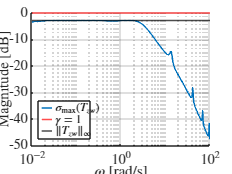


% Frequency range
W = logspace(-2, 2, 500);

% Singular Values
SV_cl = tds_sigma(cl, W);

% only the max
if size(SV_cl,2) == length(W)
    SV_max = max(SV_cl, [], 1);
else
    SV_max = max(SV_cl, [], 2).';
end

SV_cl_dB = 20*log10(SV_max);

% plot
figure; hold on

semilogx(W, SV_cl_dB, 'LineWidth',1, ...
    'DisplayName','$\sigma_{\max}(T_{zw})$');

grid on
box off

gamma = 1;

yline(20*log10(gamma),'r','LineWidth',1, ...
    'DisplayName','$\gamma = 1$');

yline(20*log10(ginf),'k','LineWidth',1, ...
    'DisplayName','$\|T_{zw}\|_\infty$');

xlabel('$\omega$ [rad/s]', 'Interpreter', 'latex')
ylabel('Magnitude [dB]', 'Interpreter', 'latex')

set(gca,'XScale','log')
xlim([1e-2 1e2])

set(gca, ...
    'FontSize',9, ...
    'GridAlpha',0.2, ...
    'TickLabelInterpreter','latex')

lgd = legend('Interpreter','latex','Location','southwest');
lgd.ItemTokenSize = [10 6];

set(gcf, 'Units', 'centimeters');
set(gcf, 'Position', [0 0 8 6]);


% export
%exportgraphics(gcf, 'cl_sigma_isl.pdf','ContentType','vector','Resolution',300);

